# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Carmen\ProbStim\RawData'];
Deci.SubjectList = 'gui';
Deci.Step               = 5;
Deci.Proceed            = false;
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\Carmen\ProbStim\ProcessedData'];

## 1. Trial Definitions

Deci.DT.Type = 'Prob_Exp';
Deci.DT.Starts     = {5 17};         %Cell Array of Markers for ETs Start.
Deci.DT.Ends       = {6 18};         %Cell Array of Markers for ETs End.
Deci.DT.Markers    = {[14 15 16] [41 42] [51 52] [31 34] [37 38] [22 23] [71] [72] [73] [74] [75] [76] [81:83] [90 91]};
Deci.DT.Locks      = [12 30 20];
Deci.DT.Toi        = [-2 3];

%MrkMake('C:\Users\User\Desktop\Prob_Stim\RawData',{{'111' '113' '115'} {'112' '114' '116'}},{'110' '117'},[-1/1000 1/1000])

Deci.DT.Block.Markers = {[100 102] 110};

## 4. Analysis

#### General Set-Up

## 5. Plotting

#### Behavioral

Deci.Analysis.Conditions    = {[14 34] [14 31] [15 34] [15 31] [16 34] [16 34]};
Deci.Analysis.CondTitle     = {'AB Cor' 'AB Inc' 'CD Cor' 'CD Inc' 'EF Cor' 'EF Inc'};

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';
Deci.Plot.Behv.Static = [14 15 16];
Deci.Plot.Behv.WriteExcel = false;

Deci.Plot.Behv.Acc.Figure = [true ];
Deci.Plot.Behv.Acc.Total = {{[1 2] [3 4] [5 6]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1] [3] [5]}};
Deci.Plot.Behv.Acc.Title = {'Percent By Condition'};
Deci.Plot.Behv.Acc.Subtitle = {{'AB Percent' 'CD Percent' 'EF Percent'}};

Deci.Plot.Behv.Acc.Block = @(c) ceil(rem(c,100));
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = false;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Movmean =  [false];
Deci.Plot.Behv.Acc.Collapse.MovWindow = 10;

Deci.Plot.Behv.RT.Figure = [true true];
Deci.Plot.Behv.RT.Draw = {{[1] [3] [5]} {[2] [4] [5]}};
Deci.Plot.Behv.RT.Title = {'Optimal Reaction Times' 'Wst. Reaction Times'};
Deci.Plot.Behv.RT.Subtitle = {{'AB' 'CD' 'EF'} {'AB' 'CD' 'EF'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = @(c) ceil(rem(c,100));
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;

Deci.Run.Behavior = true;
Deci.Run.Extra = false;

Options

Deci.Run.Behavior = true;

## ** 6. Run**

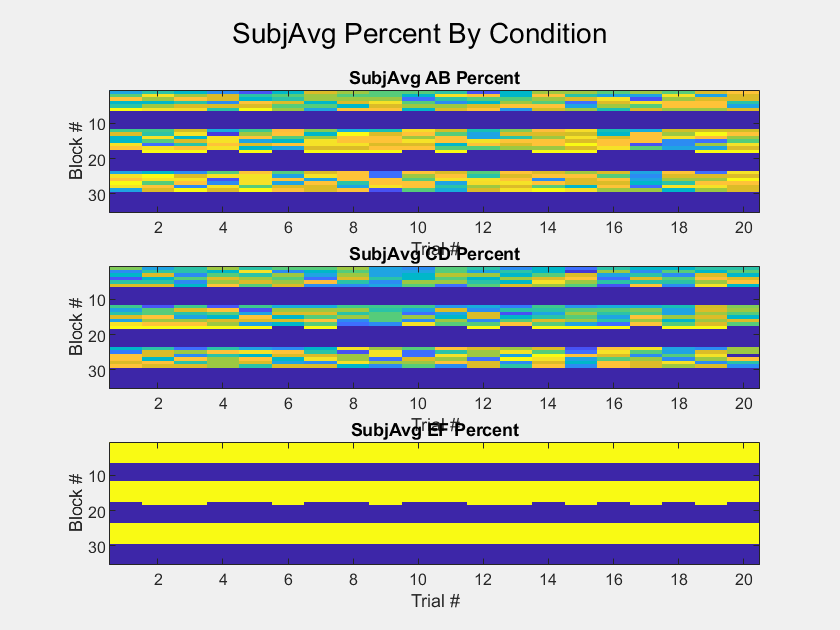

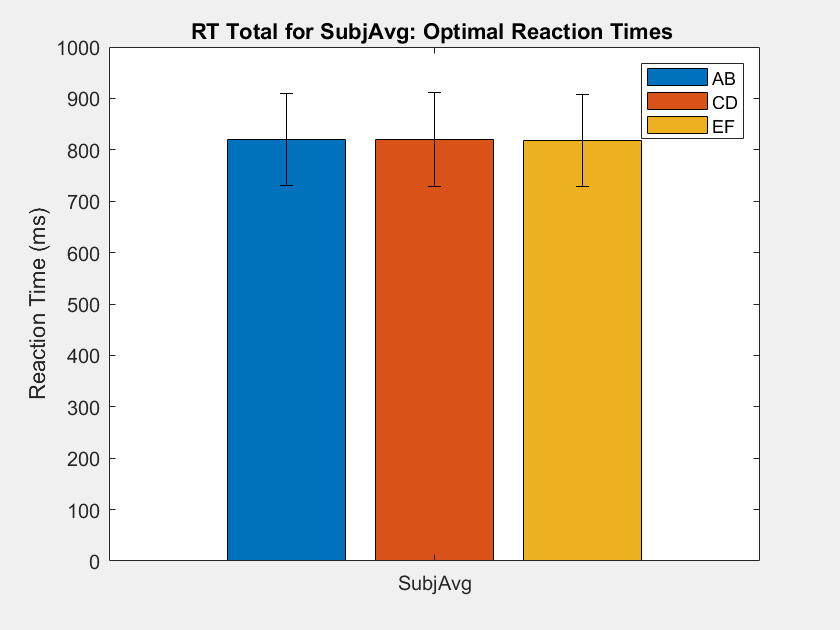

RT Total for SubjAvg AB 819.6161 +- 89.9439
RT Total for SubjAvg CD 819.5504 +- 91.7188
RT Total for SubjAvg EF 818.4171 +- 89.6312


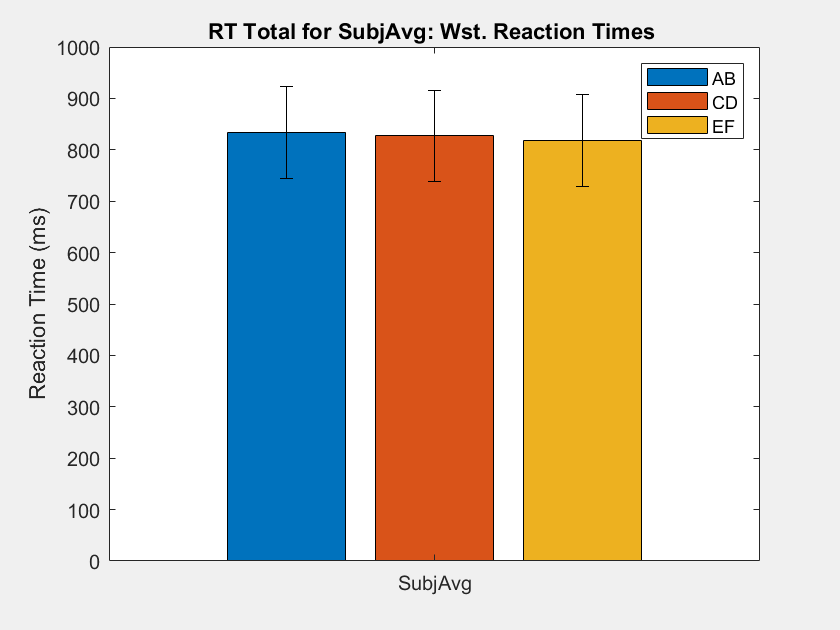

RT Total for SubjAvg AB 834.1632 +- 89.2604
RT Total for SubjAvg CD 826.9414 +- 89.0196
RT Total for SubjAvg EF 818.4171 +- 89.6312


Deci_Backend(Deci);